%% a05_p2_plot_behavioral_results

% part1: plot psychometric curve fitting for one subject, one session, with
% bootstrapping

% part2: plot delta_mu, errorbar = 1SE (68%CI) across subjects for each
% session with subj5 excluded

% part3: plot individual PSS/slope, errorbar = 1SE (68%CI) across sessions
% for each subj with subj5 excluded


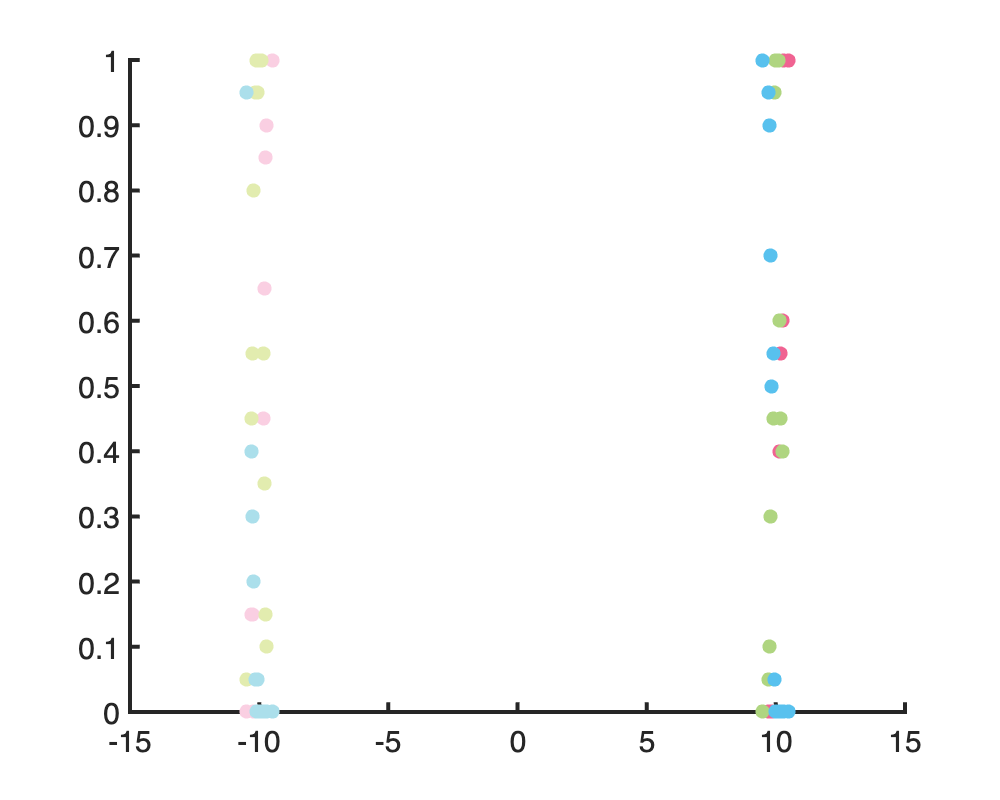

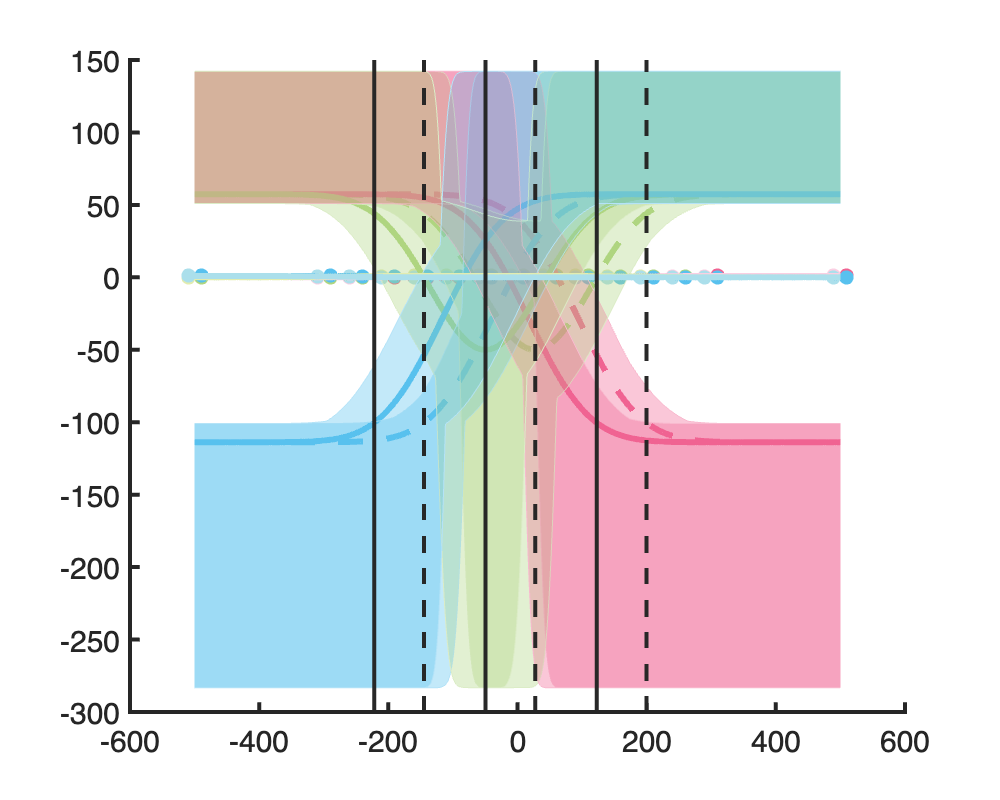

clear all; close all; clc; rng(1);

% set data path
currentDir            = pwd;
exptDir               = currentDir(1:regexp(pwd,'03expCode')-1);
outDir                = [exptDir '02figures/fig2_behavioral'];
addpath(genpath([exptDir '03ExpCode/05functions']));
addpath(genpath([exptDir '03ExpCode/06helperFunctions']));
addpath(genpath([exptDir '03ExpCode/01pretest/data']));
addpath(genpath([exptDir '03ExpCode/04posttest/data']));



% if not sorted by adaptor soa, need to sort mannually
load('best_para_1.mat')
% initiate
best_para_            = cell(all_sub(end), all_sess(end));
% sort
for s                 = all_sub
    [B, I]                = sort(idx_adaptor_soa(s,:));
    [best_para_{s,:}]     = deal(best_para{s,I});
end

% define subjects and sessions to use
all_sub               = [3,4,6:10];
all_sess              = 1:9;

% initiate
delta_criterion       = NaN(all_sub(end), all_sess(end));
% delta_mu = post_mu - pre_mu
for i                 = all_sub
    for j                 = all_sess
        delta_criterion(i,j)  = best_para_{i,j}(2) - best_para_{i,j}(1);
    end
end

% calculate group mean
mean_delta_criterion  = mean(delta_criterion, 1, 'omitnan');
se_delta_criterion    = std(delta_criterion, [], 1, 'omitnan')./sqrt(numel(all_sub));

% define axis
adaptor_soa           = [-700, -300, -200, -100,  0,  100, 200, 300, 700];

% plot delta_mu
f1                    = figure; hold on; box off;
set(gca, 'FontSize', 20, 'LineWidth', 1.5)
set(gcf, 'Position',[10 10 500 400])
alpha                 = 0.6; cMAPgray = [0, 0, 0; alpha.*ones(1,3)]; colororder(cMAPgray);

yyaxis left
errorbar(adaptor_soa, mean_delta_criterion, se_delta_criterion, ...
    'o','LineWidth', 1.5)
ylim([-150 150])
yline(0)
ylabel('\Delta_{\mu}')

% plot sorted gain excluding SOA=0
nnz_idx               = adaptor_soa ~= 0;
nnz_adaptor_soa       = adaptor_soa(nnz_idx);
gain                  = delta_criterion(:,nnz_idx)./nnz_adaptor_soa;
g_gain                = mean(gain, 1, 'omitnan');
sem_gain              = std(gain,[],1,'omitnan')./sqrt(numel(all_sub));

yyaxis right
errorbar(nnz_adaptor_soa + 20, g_gain, sem_gain, ...
    'o','LineWidth', 1.5)
ylim([-1.5 1.5])
ylabel('gain')

% look better
adaptors              = [-700, -300, -200, -100,  0,  100, 200, 300, 700];
xticks(adaptors)
xlim([min(adaptors)-50, max(adaptors)+50])
xlabel('adaptor SOA')
clear all; close all; clc; rng(1);

% if not sorted by adaptor soa, need to sort mannually
load('best_para.mat')
% initiate
best_para_            = cell(all_sub(end), all_sess(end));
% sort
for s                 = all_sub
    [B, I]                = sort(idx_adaptor_soa(s,:));
    [best_para_{s,:}]     = deal(best_para{s,I});
end

% define subjects and sessions to use
all_sub               = [3,4,6:10];
all_sess              = 1:9;

% extract pre_mu
[mu_pre, sigma_pre]   = deal(NaN(all_sub(end), all_sess(end)));
for i                 = all_sub
    for j                 = all_sess
        mu_pre(i,j)           = best_para_{i,j}(1);
        sigma_pre(i,j)        = best_para_{i,j}(3);
    end
end

% calculate mean and se across sessions, for each individual
mean_mu_pre           = mean(mu_pre, 2, 'omitnan');
se_mu_pre             = std(mu_pre, [], 2, 'omitnan')./sqrt(numel(all_sess));
mean_sigma_pre        = mean(sigma_pre, 2, 'omitnan');
se_sigma_pre          = std(sigma_pre, [], 2, 'omitnan')./sqrt(numel(all_sess));

% plotting
f2                    = figure;hold on; box off;
set(gca, 'FontSize', 20, 'LineWidth', 1.5)
set(gcf, 'Position',[10 10 500 400])
markers               = ['o','s','d','^','v','>','<','p','*','h'];

for s                 = all_sub
    errorbar(mean_mu_pre(s), mean_sigma_pre(s), ...
        se_sigma_pre(s), se_sigma_pre(s),se_mu_pre(s), se_mu_pre(s),...
        markers(s), 'MarkerSize',15, 'Color','k','LineWidth',1)
end

% look better
xlabel('PSS')
ylabel('slope')
clear all; close all; clc; rng(1);

% if not sorted by adaptor soa, need to sort mannually
load('best_para.mat')
% initiate
best_para_            = cell(all_sub(end), all_sess(end));
% sort
for s                 = all_sub
    [B, I]                = sort(idx_adaptor_soa(s,:));
    [best_para_{s,:}]     = deal(best_para{s,I});
end

% define subjects and sessions to use
all_sub               = [3,4,6:10];
all_sess              = 1:9;

% initiate
delta_criterion       = NaN(all_sub(end), all_sess(end));
for i                 = all_sub
    for j                 = all_sess
        delta_criterion(i,j)  = best_para_{i,j}(4) - best_para_{i,j}(3);
    end
end

% calculate group mean
mean_delta_sigma      = mean(delta_criterion, 1, 'omitnan');
se_delta_criterion    = std(delta_criterion, [], 1, 'omitnan')./sqrt(numel(all_sub));

% define axis
adaptor_soa           = [-700, -300, -200, -100,  0,  100, 200, 300, 700];

% plot delta_mu
f1                    = figure; hold on; box off;
set(gca, 'FontSize', 20, 'LineWidth', 1.5)
set(gcf, 'Position',[10 10 500 400])
alpha                 = 0.6; cMAPgray = [0, 0, 0; alpha.*ones(1,3)]; colororder(cMAPgray);

errorbar(adaptor_soa, mean_delta_sigma, se_delta_criterion, ...
    'o','LineWidth', 1.5)
ylim([-100 100])
yline(0)
ylabel('\Delta_{\sigma}')

% look better
adaptors              = [-700, -300, -200, -100,  0,  100, 200, 300, 700];
xticks(adaptors)
xlim([min(adaptors)-50, max(adaptors)+50])
xlabel('adaptor SOA')
clear all; close all; clc; rng(1);

% if not sorted by adaptor soa, need to sort mannually
load('best_para.mat')
% initiate
best_para_            = cell(all_sub(end), all_sess(end));
% sort
for s                 = all_sub
    [B, I]                = sort(idx_adaptor_soa(s,:));
    [best_para_{s,:}]     = deal(best_para{s,I});
end

% define subjects and sessions to use
all_sub               = [3,4,6:10];
all_sess              = 1:9;

% initiate
delta_criterion       = NaN(all_sub(end), all_sess(end));
for i                 = all_sub
    for j                 = all_sess
        delta_criterion(i,j)  = best_para_{i,j}(6) - best_para_{i,j}(5);
    end
end

% calculate group mean
mean_delta_criterion  = mean(delta_criterion, 1, 'omitnan');
se_delta_criterion    = std(delta_criterion, [], 1, 'omitnan')./sqrt(numel(all_sub));

% define axis
adaptor_soa           = [-700, -300, -200, -100,  0,  100, 200, 300, 700];

% plot delta_mu
f1                    = figure; hold on; box off;
set(gca, 'FontSize', 20, 'LineWidth', 1.5)
set(gcf, 'Position',[10 10 500 400])
alpha                 = 0.6; cMAPgray = [0, 0, 0; alpha.*ones(1,3)]; colororder(cMAPgray);

errorbar(adaptor_soa, mean_delta_criterion, se_delta_criterion, ...
    'o','LineWidth', 1.5)
ylim([-100 100])
yline(0)
ylabel('\Delta_{criterion}')

% look better
adaptors              = [-700, -300, -200, -100,  0,  100, 200, 300, 700];
xticks(adaptors)
xlim([min(adaptors)-50, max(adaptors)+50])
xlabel('adaptor SOA')